clear; close all; clc

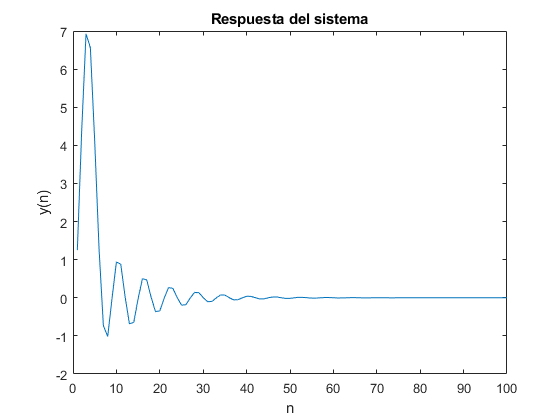

%Para 0 <= n <= 99
%Sistema 1
T1 = [1, 1/2, 1/4, 1/8, 1/16, 1/32];

%Sistema 2
T2 = [1, 1, 1, 1, 1];

%Sistema 1 en sistema 2
T1T2 = conv(T1, T2);

%Sistema 3
x = [1, zeros(1, 99)];
xn_1 = [0, x];
xn_1 = xn_1(1:100);

xn_2 = [0, 0, x];
xn_2 = xn_2(1:100);
y3 = x/4 + xn_1/2 + xn_2/4; 

%Suma sistema 1 en sistema 2 con el sistema 3
v = conv(x, T1T2);
v = v(1:100) + y3;

%Sistema 4
y = zeros(1,100);
for i = 1:100
    if i - 1 < 1
        yn_1 = 0;
        vn_1 = 0;
    else
        yn_1 = y(i - 1);
        vn_1 = v(i - 1);
    end
    
    if i - 2 < 1
        yn_2 = 0;
    else
        yn_2 = y(i - 2);
    end
    
    y(i) = 0.9*yn_1 - 0.81*yn_2 + v(i) + vn_1;
     
end

%Gráfica
figure
plot(y)
xlabel('n')
ylabel('y(n)')
title('Respuesta del sistema')